load uspsDigits.mat;
% fix so is uses the centroid of the training data and check vs the test
% data

% centroid metoden (mot 1 centroid - typ värdelös)
% fix loop and check tempDiff
%ima(testDigits(:,:,1))
randImgIndex = randi(2007)

randImgIndex = 1636

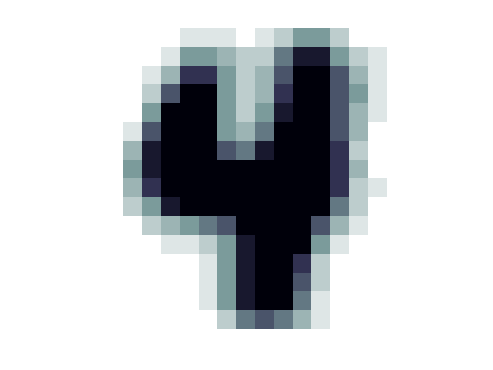


indexDigit = find(testAns == 4);

%mean(testDigits(indexDigit),3)
sumDigit = zeros(16,16,1);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,1) = sumDigit(:,:,1) + testDigits(:,:,indexValue);
end
meanDigit = sumDigit./length(indexDigit);
ima(testDigits(:,:,randImgIndex))
ima(meanDigit)


testAns(randImgIndex)

ans = 1

%tempDiff = abs(norm(meanDigit(:,:,1)) - norm(testDigits(:,:,randImgIndex)))
tempDiff = abs(norm(meanDigit(:,:,1) - testDigits(:,:,randImgIndex))) % this is the right one?

tempDiff = 5.0777

% centroid metoden
disp('new part')

new part


randImgIndex = randi(2007)

randImgIndex = 1818

results = zeros(10,1);
sumDigit = zeros(16,16,10);
for dig = 0:9
    indexDigit = find(testAns == dig);
    
    for c = 1:length(indexDigit)
        indexValue = indexDigit(c);
        testDigits(:,:,indexValue);
        sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
    end
    meanDigit = sumDigit./length(indexDigit);
    tempDiff = abs(norm(meanDigit(:,:,dig + 1) - testDigits(:,:,randImgIndex)));
    results(dig + 1) = tempDiff;
end
results

results =     5.0755
    4.7050
    4.0304
    3.5691
    2.8609
    3.6517
    4.5652
    2.6366
    3.3276
    1.6404


[M,I] = min(results);
minDigit = I-1

minDigit = 9

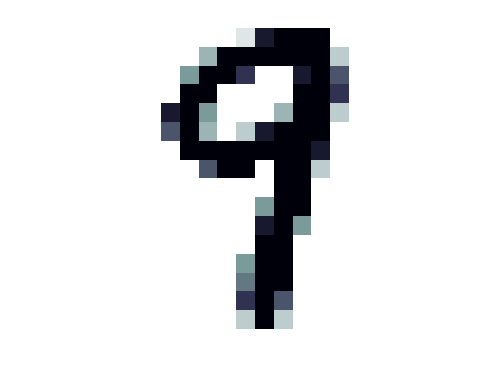

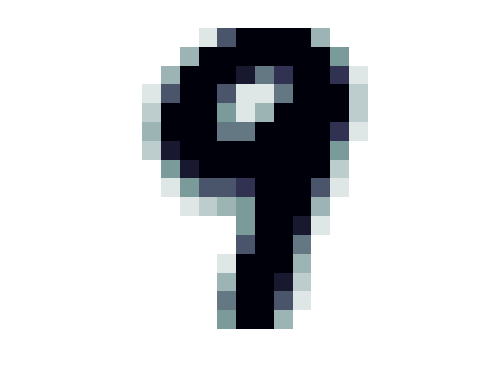

ima(testDigits(:,:,randImgIndex))
ima(sumDigit(:,:,minDigit + 1))

% closest neighbooooor
disp('new part')

new part


randImgIndex = randi(2007)

randImgIndex = 255

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;
for c = 1:2007
    if c ~= randImgIndex
        %tempDiff = abs(norm(kolTestDigits(:,:,c)) - norm(kolTestDigits(:,:,randImgIndex)));
        tempDiff = abs(norm(kolTestDigits(:,:,c) - kolTestDigits(:,:,randImgIndex)));
        if tempDiff < savedDiff
            savedDiff = tempDiff;
            savedIndex = c;
        end
    end
end 
savedIndex

savedIndex = 899

savedDiff

savedDiff = 5.8168

testAns(randImgIndex)

ans = 8

testAns(savedIndex)

ans = 8

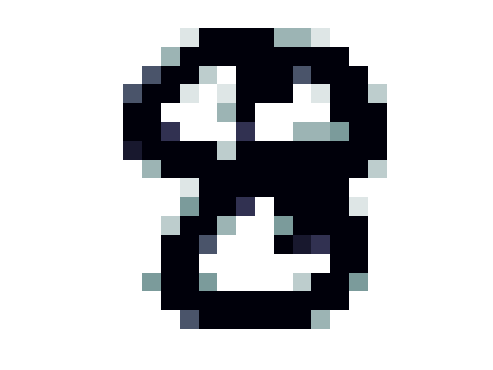

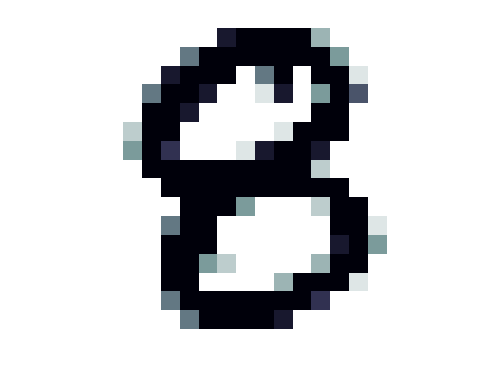

ima(testDigits(:,:,randImgIndex))
ima(testDigits(:,:,savedIndex))

% 5 closest neighbooors 
disp('new part')

new part


randImgIndex = randi(2007)

randImgIndex = 1834

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;

nClosesNeighbooorIndex = [0;0;0;0;0];
nClosesNeighbooorValues = [savedDiff;savedDiff;savedDiff;savedDiff;savedDiff];

for n = 1:5
    for c = 1:2007
        if c ~= randImgIndex && c ~= nClosesNeighbooorIndex(1) && c ~= nClosesNeighbooorIndex(2) && c ~= nClosesNeighbooorIndex(3) && c ~= nClosesNeighbooorIndex(4) && c ~= nClosesNeighbooorIndex(5)
            %tempDiff = abs(norm(kolTestDigits(:,:,c)) - norm(kolTestDigits(:,:,randImgIndex)));
            tempDiff = abs(norm(kolTestDigits(:,:,c) - kolTestDigits(:,:,randImgIndex)));

            for j = 1:5
                if tempDiff < nClosesNeighbooorValues(j)
                    nClosesNeighbooorValues(j) = tempDiff;
                    nClosesNeighbooorIndex(j) = c;
                    break;
                end
            end
        end
    end 
end

nClosesNeighbooorIndex

nClosesNeighbooorIndex =         1824
        1598
        1651
        1215
        1201


testAns(nClosesNeighbooorIndex)

ans =      1
     1
     1
     1
     1


disp(['The most common number is (multiple values occurring equally frequently, ' newline 'mode returns the smallest of those values):'])

The most common number is (multiple values occurring equally frequently, 
mode returns the smallest of those values):


mode(testAns(nClosesNeighbooorIndex))

ans = 1

nClosesNeighbooorValues

nClosesNeighbooorValues =     0.7673
    0.7769
    0.8034
    0.8385
    0.9067


testAns(randImgIndex)

ans = 1

% centroid metoden alla värden. Jag vet inte vad jag håller på med :(
disp('new part')

new part


results = zeros(10,1);
sumDigit = zeros(16,16,10);

list0 = 0;
list1 = 1;
list2 = 0;
list3 = 0;
list4 = 0;
list5 = 0;
list6 = 0;
list7 = 0;
list8 = 0;
list9 = 0;

% genererar medelvektor
indexDigit = find(testAns == 0);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit0 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 1);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit1 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 2);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit2 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 3);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit3 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 4);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit4 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 5);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit5 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 6);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit6 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 7);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit7 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 8);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit8 = sumDigit./length(indexDigit);

indexDigit = find(testAns == 9);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
end
meanDigit9 = sumDigit./length(indexDigit);

%tempDiff = zeros(10,1);

% loopar igenom alla test-siffror för att kategorisera dem
for i = 1:2007

    diff0 = abs(norm(meanDigit0(:,:,1) - testDigits(:,:,i)));
    diff1 = abs(norm(meanDigit1(:,:,1) - testDigits(:,:,i)));
    diff2 = abs(norm(meanDigit2(:,:,1) - testDigits(:,:,i)));
    diff3 = abs(norm(meanDigit3(:,:,1) - testDigits(:,:,i)));
    diff4 = abs(norm(meanDigit4(:,:,1) - testDigits(:,:,i)));
    diff5 = abs(norm(meanDigit5(:,:,1) - testDigits(:,:,i)));
    diff6 = abs(norm(meanDigit6(:,:,1) - testDigits(:,:,i)));
    diff7 = abs(norm(meanDigit7(:,:,1) - testDigits(:,:,i)));
    diff8 = abs(norm(meanDigit8(:,:,1) - testDigits(:,:,i)));
    diff9 = abs(norm(meanDigit9(:,:,1) - testDigits(:,:,i)));

    % 0
    if diff0 < diff1 && diff0 < diff2 && diff0 < tempDiff(4,1) && diff0 < tempDiff(5,1) && diff0 < tempDiff(6,1) && diff0 < tempDiff(7,1) && diff0 < tempDiff(8,1) && diff0 < tempDiff(9,1) && diff0 < tempDiff(10,1)
        list0 = [list0 testDigits(:,:,i)];
    % 1
    elseif tempDiff(2,1) < tempDiff(1,1) && tempDiff(2,1) < tempDiff(3,1) && tempDiff(2,1) < tempDiff(4,1) && tempDiff(2,1) < tempDiff(5,1) && tempDiff(2,1) < tempDiff(6,1) && tempDiff(2,1) < tempDiff(7,1) && tempDiff(2,1) < tempDiff(8,1) && tempDiff(2,1) < tempDiff(9,1) && tempDiff(2,1) < tempDiff(10,1)
        list1 = [list1 testDigits(:,:,i)];
    % 2
    elseif tempDiff(3,1) < tempDiff(1,1) && tempDiff(3,1) < tempDiff(2,1) && tempDiff(3,1) < tempDiff(4,1) && tempDiff(3,1) < tempDiff(5,1) && tempDiff(3,1) < tempDiff(6,1) && tempDiff(3,1) < tempDiff(7,1) && tempDiff(3,1) < tempDiff(8,1) && tempDiff(3,1) < tempDiff(9,1) && tempDiff(3,1) < tempDiff(10,1)
        list2 = [list2 testDigits(:,:,i)];
    % 3
    elseif tempDiff(4,1) < tempDiff(1,1) && tempDiff(4,1) < tempDiff(2,1) && tempDiff(4,1) < tempDiff(3,1) && tempDiff(4,1) < tempDiff(5,1) && tempDiff(4,1) < tempDiff(6,1) && tempDiff(4,1) < tempDiff(7,1) && tempDiff(4,1) < tempDiff(8,1) && tempDiff(4,1) < tempDiff(9,1) && tempDiff(4,1) < tempDiff(10,1)
        list3 = [list3 testDigits(:,:,i)];
    end
    clear tempDiff;
    
end

ans = 4.8277

ans = 5.3760

ans = 9.5872

ans = 9.6523

ans = 14.5116

ans = 14.0907

ans = 22.6736

ans = 20.0135

ans = 27.8789

ans = 23.7089

ans = 33.1063

ans = 29.9675

ans = 39.6366

ans = 34.9258

ans = 45.9195

ans = 40.7687

ans = 53.3732

ans = 44.4161

ans = 62.5662

ans = 50.1481

ans = 67.3650

ans = 55.1749

ans = 73.7574

ans = 60.2608

ans = 80.3410

ans = 66.6054

ans = 88.8334

ans = 72.3806

ans = 93.7363

ans = 77.8343

ans = 101.2129

ans = 80.9380

ans = 109.4322

ans = 84.9938

ans = 114.3646

ans = 91.8578

ans = 118.2661

ans = 95.5638

ans = 125.1148

ans = 100.6529

ans = 131.0390

ans = 107.1540

ans = 136.3340

ans = 111.8431

ans = 145.7208

ans = 117.8255

ans = 154.3548

ans = 125.7778

ans = 159.6870

ans = 129.3811

ans = 165.5276

ans = 135.0336

ans = 172.1892

ans = 141.1818

ans = 179.5169

ans = 145.0882

ans = 184.7926

ans = 150.2782

ans = 191.2241

ans = 155.5515

ans = 200.2440

ans = 160.9471

ans = 205.9957

ans = 167.8091

ans = 211.9356

ans = 172.2028

ans = 217.2306

ans = 177.5675

ans = 227.3995

ans = 183.0964

ans = 232.8947

ans = 187.5151

ans = 238.9194

ans = 192.5803

ans = 242.7022

ans = 198.3892

ans = 250.3608

ans = 203.5726

ans = 258.9236

ans = 209.1155

ans = 264.0958

ans = 215.2807

ans = 270.2865

ans = 218.7965

ans = 281.0703

ans = 222.6810

ans = 282.5440

ans = 230.2573

ans = 291.2245

ans = 234.5778

ans = 299.1656

ans = 236.9529

ans = 299.6174

ans = 244.8567

ans = 312.2827

ans = 250.8938

ans = 316.9743

ans = 256.4900

ans = 323.0698

ans = 262.3458

ans = 328.3831

ans = 267.1546

ans = 336.0132

ans = 271.9434

ans = 344.4102

ans = 274.6793

ans = 349.2786

ans = 282.6823

ans = 354.2694

ans = 288.2019

ans = 364.3500

ans = 292.5872

ans = 370.8756

ans = 297.3782

ans = 378.2036

ans = 303.4643

ans = 381.6127

ans = 307.6662

ans = 385.2998

ans = 313.7291

ans = 396.7942

ans = 317.9114

ans = 398.2648

ans = 323.9323

ans = 410.4156

ans = 329.5267

ans = 418.1542

ans = 336.2933

ans = 421.4304

ans = 341.8614

ans = 430.3740

ans = 346.0463

ans = 439.2951

ans = 350.1823

ans = 441.7625

ans = 357.2226

ans = 449.1165

ans = 362.6164

ans = 458.2918

ans = 364.9116

ans = 461.2680

ans = 371.5171

ans = 467.7146

ans = 377.4885

ans = 476.2394

ans = 383.2028

ans = 481.1775

ans = 387.5603

ans = 484.6994

ans = 391.6407

ans = 494.2173

ans = 397.8448

ans = 499.8479

ans = 402.8774

ans = 510.0319

ans = 406.5727

ans = 516.0726

ans = 415.4175

ans = 523.4363

ans = 418.2916

ans = 530.0919

ans = 426.5164

ans = 533.9561

ans = 432.0098

ans = 542.9297

ans = 436.9705

ans = 546.6588

ans = 441.6983

ans = 552.5337

ans = 445.9808

ans = 560.0376

ans = 451.7751

ans = 568.0445

ans = 457.0738

ans = 572.4521

ans = 462.7429

ans = 576.8817

ans = 466.1142

ans = 582.2959

ans = 471.9565

ans = 594.5724

ans = 476.3130

ans = 596.6860

ans = 481.7640

ans = 608.3028

ans = 487.1937

ans = 611.4830

ans = 493.0609

ans = 619.0950

ans = 498.1091

ans = 624.8173

ans = 505.7660

ans = 634.8614

ans = 510.2343

ans = 638.4172

ans = 516.6284

ans = 645.4314

ans = 521.7162

ans = 652.7169

ans = 526.0839

ans = 658.1879

ans = 532.1652

ans = 664.6126

ans = 536.3667

ans = 674.4612

ans = 542.2120

ans = 680.1650

ans = 546.0866

ans = 681.4460

ans = 551.2365

ans = 695.6956

ans = 558.8828

ans = 699.7546

ans = 563.0459

ans = 705.9339

ans = 567.9523

ans = 713.2987

ans = 575.2604

ans = 721.0649

ans = 579.9131

ans = 725.2614

ans = 585.4152

ans = 731.5420

ans = 589.7083

ans = 740.0789

ans = 595.3046

ans = 746.8175

ans = 600.6982

ans = 754.0176

ans = 606.6705

ans = 757.7904

ans = 612.0251

ans = 764.7375

ans = 616.1872

ans = 772.2956

ans = 621.1435

ans = 778.4215

ans = 626.1559

ans = 785.7714

ans = 632.5452

ans = 792.1291

ans = 637.5615

ans = 797.8425

ans = 643.5855

ans = 805.2788

ans = 648.7962

ans = 808.4035

ans = 653.6664

ans = 818.5742

ans = 659.6834

ans = 822.9983

ans = 663.3110

ans = 829.9176

ans = 668.5038

ans = 838.1443

ans = 673.9078

ans = 845.7969

ans = 676.7183

ans = 853.2857

ans = 685.1572

ans = 857.0122

ans = 690.3956

ans = 866.4869

ans = 697.4470

ans = 871.2926

ans = 702.4181

ans = 878.5334

ans = 702.9556

ans = 886.0645

ans = 713.8185

ans = 890.4730

ans = 715.7291

ans = 892.4233

ans = 721.0129

ans = 898.7939

ans = 725.5841

ans = 910.5006

ans = 733.4029

ans = 917.4537

ans = 738.1575

ans = 923.3336

ans = 742.9236

ans = 927.7117

ans = 746.9211

ans = 934.7546

ans = 752.0998

ans = 941.3739

ans = 758.8084

ans = 947.2707

ans = 763.8358

ans = 954.1596

ans = 769.2876

ans = 960.2606

ans = 773.9707

ans = 967.9185

ans = 779.8503

ans = 972.6139

ans = 784.9604

ans = 984.0695

ans = 791.8472

ans = 989.3521

ans = 795.9730

ans = 995.3173

ans = 802.1634

ans = 1.0020e+03

ans = 807.2711

ans = 1.0111e+03

ans = 813.9755

ans = 1.0162e+03

ans = 816.7043

ans = 1.0236e+03

ans = 821.9048

ans = 1.0311e+03

ans = 826.3457

ans = 1.0334e+03

ans = 831.8507

ans = 1.0437e+03

ans = 835.7906

ans = 1.0487e+03

ans = 845.3387

ans = 1.0548e+03

ans = 850.2565

ans = 1.0619e+03

ans = 855.7888

ans = 1.0682e+03

ans = 861.1225

ans = 1.0756e+03

ans = 866.2792

ans = 1.0799e+03

ans = 868.5928

ans = 1.0876e+03

ans = 876.1664

ans = 1.0953e+03

ans = 882.3562

ans = 1.1015e+03

ans = 887.5133

ans = 1.1073e+03

ans = 892.0221

ans = 1.1139e+03

ans = 897.4404

ans = 1.1224e+03

ans = 904.3550

ans = 1.1274e+03

ans = 908.8759

ans = 1.1354e+03

ans = 913.6803

ans = 1.1389e+03

ans = 917.6926

ans = 1.1473e+03

ans = 924.0530

ans = 1.1511e+03

ans = 928.5059

ans = 1.1596e+03

ans = 931.5376

ans = 1.1655e+03

ans = 938.0915

ans = 1.1734e+03

ans = 946.1705

ans = 1.1816e+03

ans = 950.0255

ans = 1.1894e+03

ans = 953.3653

ans = 1.1927e+03

ans = 961.0189

ans = 1.2012e+03

ans = 965.5770

ans = 1.2042e+03

ans = 971.2243

ans = 1.2139e+03

ans = 977.9304

ans = 1.2196e+03

ans = 981.2967

ans = 1.2259e+03

ans = 985.4377

ans = 1.2332e+03

ans = 993.1760

ans = 1.2418e+03

ans = 995.4270

ans = 1.2472e+03

ans = 1.0018e+03

ans = 1.2547e+03

ans = 1.0058e+03

ans = 1.2585e+03

ans = 1.0112e+03

ans = 1.2684e+03

ans = 1.0170e+03

ans = 1.2699e+03

ans = 1.0238e+03

ans = 1.2781e+03

ans = 1.0301e+03

ans = 1.2850e+03

ans = 1.0344e+03

ans = 1.2935e+03

ans = 1.0410e+03

ans = 1.2983e+03

ans = 1.0454e+03

ans = 1.3065e+03

ans = 1.0513e+03

ans = 1.3111e+03

ans = 1.0559e+03

ans = 1.3188e+03

ans = 1.0617e+03

ans = 1.3277e+03

ans = 1.0659e+03

ans = 1.3314e+03

ans = 1.0716e+03

ans = 1.3368e+03

ans = 1.0776e+03

ans = 1.3428e+03

ans = 1.0820e+03

ans = 1.3496e+03

ans = 1.0880e+03

ans = 1.3598e+03

ans = 1.0902e+03

ans = 1.3621e+03

ans = 1.0969e+03

ans = 1.3674e+03

ans = 1.1031e+03

ans = 1.3737e+03

ans = 1.1086e+03

ans = 1.3851e+03

ans = 1.1105e+03

ans = 1.3893e+03

ans = 1.1181e+03

ans = 1.3975e+03

ans = 1.1228e+03

ans = 1.4035e+03

ans = 1.1306e+03

ans = 1.4105e+03

ans = 1.1332e+03

ans = 1.4178e+03

ans = 1.1403e+03

ans = 1.4249e+03

ans = 1.1456e+03

ans = 1.4311e+03

ans = 1.1501e+03

ans = 1.4352e+03

ans = 1.1570e+03

ans = 1.4436e+03

ans = 1.1608e+03

ans = 1.4487e+03

ans = 1.1677e+03

ans = 1.4578e+03

ans = 1.1722e+03

ans = 1.4605e+03

ans = 1.1762e+03

ans = 1.4669e+03

ans = 1.1829e+03

ans = 1.4732e+03

ans = 1.1872e+03

ans = 1.4801e+03

ans = 1.1928e+03

ans = 1.4905e+03

ans = 1.1954e+03

ans = 1.4948e+03

ans = 1.2027e+03

ans = 1.4994e+03

ans = 1.2089e+03

ans = 1.5091e+03

ans = 1.2136e+03

ans = 1.5147e+03

ans = 1.2192e+03

ans = 1.5212e+03

ans = 1.2246e+03

ans = 1.5296e+03

ans = 1.2309e+03

ans = 1.5358e+03

ans = 1.2339e+03

ans = 1.5419e+03

ans = 1.2389e+03

ans = 1.5508e+03

ans = 1.2451e+03

ans = 1.5557e+03

ans = 1.2521e+03

ans = 1.5626e+03

ans = 1.2575e+03

ans = 1.5709e+03

ans = 1.2603e+03

ans = 1.5757e+03

ans = 1.2683e+03

ans = 1.5825e+03

ans = 1.2734e+03

ans = 1.5859e+03

ans = 1.2765e+03

ans = 1.5928e+03

ans = 1.2815e+03

ans = 1.6026e+03

ans = 1.2854e+03

ans = 1.6055e+03

ans = 1.2932e+03

ans = 1.6146e+03

ans = 1.3008e+03

ans = 1.6195e+03

ans = 1.3033e+03

ans = 1.6276e+03

ans = 1.3089e+03

ans = 1.6354e+03

ans = 1.3118e+03

ans = 1.6374e+03

ans = 1.3179e+03

ans = 1.6484e+03

ans = 1.3222e+03

ans = 1.6500e+03

ans = 1.3292e+03

ans = 1.6617e+03

ans = 1.3362e+03

ans = 1.6680e+03

ans = 1.3412e+03

ans = 1.6710e+03

ans = 1.3460e+03

ans = 1.6810e+03

ans = 1.3527e+03

ans = 1.6868e+03

ans = 1.3583e+03

ans = 1.6917e+03

ans = 1.3634e+03

ans = 1.7020e+03

ans = 1.3695e+03

ans = 1.7050e+03

ans = 1.3728e+03

ans = 1.7145e+03

ans = 1.3802e+03

ans = 1.7213e+03

ans = 1.3844e+03

ans = 1.7276e+03

ans = 1.3895e+03

ans = 1.7300e+03

ans = 1.3948e+03

ans = 1.7385e+03

ans = 1.3995e+03

ans = 1.7476e+03

ans = 1.4034e+03

ans = 1.7531e+03

ans = 1.4117e+03

ans = 1.7596e+03

ans = 1.4167e+03

ans = 1.7642e+03

ans = 1.4209e+03

ans = 1.7700e+03

ans = 1.4258e+03

ans = 1.7781e+03

ans = 1.4317e+03

ans = 1.7849e+03

ans = 1.4369e+03

ans = 1.7901e+03

ans = 1.4425e+03

ans = 1.8010e+03

ans = 1.4452e+03

ans = 1.8037e+03

ans = 1.4518e+03

ans = 1.8109e+03

ans = 1.4568e+03

ans = 1.8172e+03

ans = 1.4607e+03

ans = 1.8226e+03

ans = 1.4656e+03

ans = 1.8300e+03

ans = 1.4727e+03

ans = 1.8364e+03

ans = 1.4795e+03

ans = 1.8452e+03

ans = 1.4853e+03

ans = 1.8509e+03

ans = 1.4896e+03

ans = 1.8548e+03

ans = 1.4948e+03

ans = 1.8637e+03

ans = 1.5008e+03

ans = 1.8723e+03

ans = 1.5061e+03

ans = 1.8776e+03

ans = 1.5107e+03

ans = 1.8845e+03

ans = 1.5162e+03

ans = 1.8896e+03

ans = 1.5226e+03

ans = 1.8989e+03

ans = 1.5237e+03

ans = 1.9052e+03

ans = 1.5337e+03

ans = 1.9111e+03

ans = 1.5373e+03

ans = 1.9180e+03

ans = 1.5416e+03

ans = 1.9249e+03

ans = 1.5488e+03

ans = 1.9299e+03

ans = 1.5533e+03

ans = 1.9372e+03

ans = 1.5584e+03

ans = 1.9423e+03

ans = 1.5613e+03

ans = 1.9498e+03

ans = 1.5676e+03

ans = 1.9532e+03

ans = 1.5720e+03

ans = 1.9613e+03

ans = 1.5787e+03

ans = 1.9706e+03

ans = 1.5853e+03

ans = 1.9761e+03

ans = 1.5904e+03

ans = 1.9830e+03

ans = 1.5956e+03

ans = 1.9894e+03

ans = 1.6010e+03

ans = 1.9966e+03

ans = 1.6054e+03

ans = 2.0030e+03

ans = 1.6109e+03

ans = 2.0090e+03

ans = 1.6173e+03

ans = 2.0165e+03

ans = 1.6220e+03

ans = 2.0227e+03

ans = 1.6270e+03

ans = 2.0282e+03

ans = 1.6309e+03

ans = 2.0343e+03

ans = 1.6366e+03

ans = 2.0418e+03

ans = 1.6424e+03

ans = 2.0470e+03

ans = 1.6483e+03

ans = 2.0558e+03

ans = 1.6549e+03

ans = 2.0621e+03

ans = 1.6587e+03

ans = 2.0707e+03

ans = 1.6621e+03

ans = 2.0738e+03

ans = 1.6710e+03

ans = 2.0840e+03

ans = 1.6730e+03

ans = 2.0908e+03

ans = 1.6786e+03

ans = 2.0975e+03

ans = 1.6845e+03

ans = 2.1017e+03

ans = 1.6907e+03

ans = 2.1100e+03

ans = 1.6971e+03

ans = 2.1163e+03

ans = 1.7018e+03

ans = 2.1222e+03

ans = 1.7065e+03

ans = 2.1281e+03

ans = 1.7131e+03

ans = 2.1329e+03

ans = 1.7182e+03

ans = 2.1436e+03

ans = 1.7226e+03

ans = 2.1491e+03

ans = 1.7285e+03

ans = 2.1536e+03

ans = 1.7311e+03

ans = 2.1633e+03

ans = 1.7371e+03

ans = 2.1674e+03

ans = 1.7428e+03

ans = 2.1734e+03

ans = 1.7488e+03

ans = 2.1803e+03

ans = 1.7537e+03

ans = 2.1878e+03

ans = 1.7593e+03

ans = 2.1909e+03

ans = 1.7643e+03

ans = 2.1988e+03

ans = 1.7695e+03

ans = 2.2069e+03

ans = 1.7759e+03

ans = 2.2118e+03

ans = 1.7816e+03

ans = 2.2181e+03

ans = 1.7868e+03

ans = 2.2251e+03

ans = 1.7911e+03

ans = 2.2329e+03

ans = 1.7970e+03

ans = 2.2399e+03

ans = 1.8031e+03

ans = 2.2486e+03

ans = 1.8053e+03

ans = 2.2539e+03

ans = 1.8133e+03

ans = 2.2621e+03

ans = 1.8163e+03

ans = 2.2650e+03

ans = 1.8223e+03

ans = 2.2715e+03

ans = 1.8285e+03

ans = 2.2796e+03

ans = 1.8301e+03

ans = 2.2859e+03

ans = 1.8407e+03

ans = 2.2941e+03

ans = 1.8417e+03

ans = 2.3011e+03

ans = 1.8503e+03

ans = 2.3068e+03

ans = 1.8565e+03

ans = 2.3129e+03

ans = 1.8615e+03

ans = 2.3205e+03

ans = 1.8671e+03

ans = 2.3274e+03

ans = 1.8731e+03

ans = 2.3341e+03

ans = 1.8752e+03

ans = 2.3367e+03

ans = 1.8813e+03

ans = 2.3439e+03

ans = 1.8877e+03

ans = 2.3513e+03

ans = 1.8933e+03

ans = 2.3608e+03

ans = 1.8958e+03

ans = 2.3664e+03

ans = 1.8998e+03

ans = 2.3688e+03

ans = 1.9075e+03

ans = 2.3758e+03

ans = 1.9130e+03

ans = 2.3857e+03

ans = 1.9153e+03

ans = 2.3916e+03

ans = 1.9236e+03

ans = 2.4000e+03

ans = 1.9270e+03

ans = 2.4023e+03

ans = 1.9348e+03

ans = 2.4085e+03

ans = 1.9405e+03

ans = 2.4156e+03

ans = 1.9460e+03

ans = 2.4262e+03

ans = 1.9519e+03

ans = 2.4329e+03

ans = 1.9538e+03

ans = 2.4350e+03

ans = 1.9617e+03

ans = 2.4415e+03

ans = 1.9671e+03

ans = 2.4519e+03

ans = 1.9686e+03

ans = 2.4578e+03

ans = 1.9778e+03

ans = 2.4653e+03

ans = 1.9801e+03

ans = 2.4677e+03

ans = 1.9864e+03

ans = 2.4731e+03

ans = 1.9916e+03

ans = 2.4842e+03

ans = 1.9989e+03

ans = 2.4876e+03

ans = 2.0028e+03

ans = 2.4980e+03

ans = 2.0058e+03

ans = 2.5039e+03

ans = 2.0129e+03

ans = 2.5102e+03

ans = 2.0189e+03

ans = 2.5164e+03

ans = 2.0245e+03

ans = 2.5242e+03

ans = 2.0268e+03

ans = 2.5255e+03

ans = 2.0341e+03

ans = 2.5374e+03

ans = 2.0374e+03

ans = 2.5404e+03

ans = 2.0459e+03

ans = 2.5476e+03

ans = 2.0499e+03

ans = 2.5575e+03

ans = 2.0537e+03

ans = 2.5594e+03

ans = 2.0619e+03

ans = 2.5700e+03

ans = 2.0636e+03

ans = 2.5724e+03

ans = 2.0724e+03

ans = 2.5834e+03

ans = 2.0744e+03

ans = 2.5905e+03

ans = 2.0811e+03

ans = 2.5921e+03

ans = 2.0879e+03

ans = 2.5988e+03

ans = 2.0931e+03

ans = 2.6053e+03

ans = 2.0993e+03

ans = 2.6170e+03

ans = 2.1015e+03

ans = 2.6238e+03

ans = 2.1072e+03

ans = 2.6256e+03

ans = 2.1143e+03

ans = 2.6365e+03

ans = 2.1172e+03

ans = 2.6407e+03

ans = 2.1242e+03

ans = 2.6477e+03

ans = 2.1302e+03

ans = 2.6565e+03

ans = 2.1333e+03

ans = 2.6594e+03

ans = 2.1417e+03

ans = 2.6656e+03

ans = 2.1469e+03

ans = 2.6731e+03

ans = 2.1516e+03

ans = 2.6791e+03

ans = 2.1564e+03

ans = 2.6875e+03

ans = 2.1584e+03

ans = 2.6897e+03

ans = 2.1659e+03

ans = 2.6956e+03

ans = 2.1712e+03

ans = 2.7022e+03

ans = 2.1753e+03

ans = 2.7141e+03

ans = 2.1796e+03

ans = 2.7223e+03

ans = 2.1861e+03

ans = 2.7252e+03

ans = 2.1944e+03

ans = 2.7328e+03

ans = 2.1988e+03

ans = 2.7382e+03

ans = 2.2029e+03

ans = 2.7473e+03

ans = 2.2100e+03

ans = 2.7545e+03

ans = 2.2124e+03

ans = 2.7564e+03

ans = 2.2166e+03

ans = 2.7609e+03

ans = 2.2241e+03

ans = 2.7727e+03

ans = 2.2273e+03

ans = 2.7766e+03

ans = 2.2359e+03

ans = 2.7863e+03

ans = 2.2389e+03

ans = 2.7876e+03

ans = 2.2453e+03

ans = 2.7947e+03

ans = 2.2504e+03

ans = 2.8010e+03

ans = 2.2561e+03

ans = 2.8106e+03

ans = 2.2620e+03

ans = 2.8203e+03

ans = 2.2649e+03

ans = 2.8217e+03

ans = 2.2726e+03

ans = 2.8298e+03

ans = 2.2791e+03

ans = 2.8366e+03

ans = 2.2831e+03

ans = 2.8442e+03

ans = 2.2896e+03

ans = 2.8535e+03

ans = 2.2945e+03

ans = 2.8601e+03

ans = 2.3003e+03

ans = 2.8678e+03

ans = 2.3039e+03

ans = 2.8740e+03

ans = 2.3114e+03

ans = 2.8789e+03

ans = 2.3162e+03

ans = 2.8828e+03

ans = 2.3193e+03

ans = 2.8918e+03

ans = 2.3252e+03

ans = 2.8998e+03

ans = 2.3289e+03

ans = 2.9024e+03

ans = 2.3360e+03

ans = 2.9101e+03

ans = 2.3408e+03

ans = 2.9173e+03

ans = 2.3466e+03

ans = 2.9237e+03

ans = 2.3533e+03

ans = 2.9313e+03

ans = 2.3573e+03

ans = 2.9368e+03

ans = 2.3635e+03

ans = 2.9434e+03

ans = 2.3680e+03

ans = 2.9511e+03

ans = 2.3751e+03

ans = 2.9592e+03

ans = 2.3798e+03

ans = 2.9665e+03

ans = 2.3833e+03

ans = 2.9731e+03

ans = 2.3888e+03

ans = 2.9794e+03

ans = 2.3966e+03

ans = 2.9801e+03

ans = 2.4000e+03

ans = 2.9868e+03

ans = 2.4050e+03

ans = 2.9937e+03

ans = 2.4088e+03

ans = 2.9995e+03

ans = 2.4147e+03

ans = 3.0093e+03

ans = 2.4205e+03

ans = 3.0120e+03

ans = 2.4255e+03

ans = 3.0219e+03

ans = 2.4336e+03

ans = 3.0279e+03

ans = 2.4358e+03

ans = 3.0326e+03

ans = 2.4416e+03

ans = 3.0431e+03

ans = 2.4495e+03

ans = 3.0496e+03

ans = 2.4533e+03

ans = 3.0564e+03

ans = 2.4575e+03

ans = 3.0616e+03

ans = 2.4633e+03

ans = 3.0706e+03

ans = 2.4694e+03

ans = 3.0773e+03

ans = 2.4727e+03

ans = 3.0806e+03

ans = 2.4772e+03

ans = 3.0888e+03

ans = 2.4826e+03

ans = 3.0922e+03

ans = 2.4874e+03

ans = 3.0966e+03

ans = 2.4936e+03

ans = 3.1072e+03

ans = 2.5011e+03

ans = 3.1160e+03

ans = 2.5069e+03

ans = 3.1207e+03

ans = 2.5123e+03

ans = 3.1279e+03

ans = 2.5178e+03

ans = 3.1353e+03

ans = 2.5213e+03

ans = 3.1430e+03

ans = 2.5283e+03

ans = 3.1482e+03

ans = 2.5333e+03

ans = 3.1512e+03

ans = 2.5368e+03

ans = 3.1618e+03

ans = 2.5435e+03

ans = 3.1662e+03

ans = 2.5484e+03

ans = 3.1755e+03

ans = 2.5536e+03

ans = 3.1824e+03

ans = 2.5599e+03

ans = 3.1883e+03

ans = 2.5641e+03

ans = 3.1921e+03

ans = 2.5707e+03

ans = 3.2031e+03

ans = 2.5732e+03

ans = 3.2080e+03

ans = 2.5790e+03

ans = 3.2139e+03

ans = 2.5847e+03

ans = 3.2211e+03

ans = 2.5902e+03

ans = 3.2276e+03

ans = 2.5966e+03

ans = 3.2333e+03

ans = 2.6015e+03

ans = 3.2345e+03

ans = 2.6049e+03

ans = 3.2404e+03

ans = 2.6089e+03

ans = 3.2508e+03

ans = 2.6155e+03

ans = 3.2594e+03

ans = 2.6213e+03

ans = 3.2677e+03

ans = 2.6302e+03

ans = 3.2741e+03

ans = 2.6335e+03

ans = 3.2805e+03

ans = 2.6388e+03

ans = 3.2871e+03

ans = 2.6440e+03

ans = 3.2931e+03

ans = 2.6489e+03

ans = 3.2994e+03

ans = 2.6565e+03

ans = 3.3055e+03

ans = 2.6606e+03

ans = 3.3149e+03

ans = 2.6632e+03

ans = 3.3205e+03

ans = 2.6704e+03

ans = 3.3249e+03

ans = 2.6767e+03

ans = 3.3343e+03

ans = 2.6803e+03

ans = 3.3386e+03

ans = 2.6854e+03

ans = 3.3466e+03

ans = 2.6916e+03

ans = 3.3496e+03

ans = 2.6962e+03

ans = 3.3588e+03

ans = 2.7015e+03

ans = 3.3662e+03

ans = 2.7096e+03

ans = 3.3715e+03

ans = 2.7135e+03

ans = 3.3812e+03

ans = 2.7172e+03

ans = 3.3878e+03

ans = 2.7225e+03

ans = 3.3930e+03

ans = 2.7298e+03

ans = 3.3972e+03

ans = 2.7341e+03

ans = 3.4071e+03

ans = 2.7375e+03

ans = 3.4101e+03

ans = 2.7451e+03

ans = 3.4180e+03

ans = 2.7514e+03

ans = 3.4249e+03

ans = 2.7557e+03

ans = 3.4290e+03

ans = 2.7584e+03

ans = 3.4329e+03

ans = 2.7621e+03

ans = 3.4432e+03

ans = 2.7690e+03

ans = 3.4516e+03

ans = 2.7728e+03

ans = 3.4556e+03

ans = 2.7797e+03

ans = 3.4610e+03

ans = 2.7862e+03

ans = 3.4695e+03

ans = 2.7920e+03

ans = 3.4755e+03

ans = 2.7969e+03

ans = 3.4810e+03

ans = 2.8029e+03

ans = 3.4885e+03

ans = 2.8080e+03

ans = 3.4957e+03

ans = 2.8123e+03

ans = 3.5021e+03

ans = 2.8175e+03

ans = 3.5095e+03

ans = 2.8238e+03

ans = 3.5180e+03

ans = 2.8267e+03

ans = 3.5250e+03

ans = 2.8320e+03

ans = 3.5274e+03

ans = 2.8380e+03

ans = 3.5348e+03

ans = 2.8434e+03

ans = 3.5393e+03

ans = 2.8491e+03

ans = 3.5471e+03

ans = 2.8522e+03

ans = 3.5556e+03

ans = 2.8604e+03

ans = 3.5635e+03

ans = 2.8667e+03

ans = 3.5706e+03

ans = 2.8733e+03

ans = 3.5754e+03

ans = 2.8770e+03

ans = 3.5841e+03

ans = 2.8795e+03

ans = 3.5885e+03

ans = 2.8861e+03

ans = 3.5965e+03

ans = 2.8931e+03

ans = 3.6021e+03

ans = 2.8975e+03

ans = 3.6087e+03

ans = 2.9030e+03

ans = 3.6169e+03

ans = 2.9086e+03

ans = 3.6216e+03

ans = 2.9155e+03

ans = 3.6278e+03

ans = 2.9199e+03

ans = 3.6343e+03

ans = 2.9256e+03

ans = 3.6414e+03

ans = 2.9311e+03

ans = 3.6480e+03

ans = 2.9365e+03

ans = 3.6554e+03

ans = 2.9402e+03

ans = 3.6605e+03

ans = 2.9449e+03

ans = 3.6666e+03

ans = 2.9503e+03

ans = 3.6729e+03

ans = 2.9555e+03

ans = 3.6827e+03

ans = 2.9587e+03

ans = 3.6883e+03

ans = 2.9665e+03

ans = 3.6930e+03

ans = 2.9724e+03

ans = 3.6998e+03

ans = 2.9786e+03

ans = 3.7065e+03

ans = 2.9834e+03

ans = 3.7133e+03

ans = 2.9882e+03

ans = 3.7205e+03

ans = 2.9933e+03

ans = 3.7270e+03

ans = 2.9987e+03

ans = 3.7313e+03

ans = 3.0025e+03

ans = 3.7387e+03

ans = 3.0082e+03

ans = 3.7443e+03

ans = 3.0121e+03

ans = 3.7550e+03

ans = 3.0195e+03

ans = 3.7610e+03

ans = 3.0246e+03

ans = 3.7690e+03

ans = 3.0285e+03

ans = 3.7738e+03

ans = 3.0361e+03

ans = 3.7794e+03

ans = 3.0421e+03

ans = 3.7877e+03

ans = 3.0478e+03

ans = 3.7904e+03

ans = 3.0506e+03

ans = 3.7999e+03

ans = 3.0561e+03

ans = 3.8082e+03

ans = 3.0604e+03

ans = 3.8111e+03

ans = 3.0661e+03

ans = 3.8196e+03

ans = 3.0726e+03

ans = 3.8247e+03

ans = 3.0780e+03

ans = 3.8288e+03

ans = 3.0815e+03

ans = 3.8409e+03

ans = 3.0862e+03

ans = 3.8469e+03

ans = 3.0954e+03

ans = 3.8551e+03

ans = 3.0985e+03

ans = 3.8606e+03

ans = 3.1065e+03

ans = 3.8657e+03

ans = 3.1099e+03

ans = 3.8730e+03

ans = 3.1153e+03

ans = 3.8780e+03

ans = 3.1205e+03

ans = 3.8859e+03

ans = 3.1260e+03

ans = 3.8916e+03

ans = 3.1310e+03

ans = 3.8975e+03

ans = 3.1353e+03

ans = 3.9068e+03

ans = 3.1394e+03

ans = 3.9114e+03

ans = 3.1470e+03

ans = 3.9185e+03

ans = 3.1522e+03

ans = 3.9237e+03

ans = 3.1583e+03

ans = 3.9300e+03

ans = 3.1631e+03

ans = 3.9371e+03

ans = 3.1672e+03

ans = 3.9436e+03

ans = 3.1732e+03

ans = 3.9488e+03

ans = 3.1771e+03

ans = 3.9533e+03

ans = 3.1826e+03

ans = 3.9590e+03

ans = 3.1881e+03

ans = 3.9694e+03

ans = 3.1938e+03

ans = 3.9770e+03

ans = 3.1995e+03

ans = 3.9850e+03

ans = 3.2018e+03

ans = 3.9899e+03

ans = 3.2100e+03

ans = 3.9951e+03

ans = 3.2159e+03

ans = 4.0041e+03

ans = 3.2172e+03

ans = 4.0100e+03

ans = 3.2260e+03

ans = 4.0130e+03

ans = 3.2298e+03

ans = 4.0199e+03

ans = 3.2346e+03

ans = 4.0243e+03

ans = 3.2409e+03

ans = 4.0317e+03

ans = 3.2444e+03

ans = 4.0416e+03

ans = 3.2496e+03

ans = 4.0459e+03

ans = 3.2575e+03

ans = 4.0544e+03

ans = 3.2617e+03

ans = 4.0588e+03

ans = 3.2654e+03

ans = 4.0651e+03

ans = 3.2713e+03

ans = 4.0779e+03

ans = 3.2767e+03

ans = 4.0824e+03

ans = 3.2832e+03

ans = 4.0899e+03

ans = 3.2905e+03

ans = 4.0979e+03

ans = 3.2930e+03

ans = 4.1048e+03

ans = 3.3024e+03

ans = 4.1084e+03

ans = 3.3057e+03

ans = 4.1157e+03

ans = 3.3100e+03

ans = 4.1205e+03

ans = 3.3164e+03

ans = 4.1285e+03

ans = 3.3214e+03

ans = 4.1378e+03

ans = 3.3254e+03

ans = 4.1412e+03

ans = 3.3320e+03

ans = 4.1475e+03

ans = 3.3375e+03

ans = 4.1535e+03

ans = 3.3426e+03

ans = 4.1613e+03

ans = 3.3479e+03

ans = 4.1665e+03

ans = 3.3539e+03

ans = 4.1730e+03

ans = 3.3578e+03

ans = 4.1794e+03

ans = 3.3633e+03

ans = 4.1865e+03

ans = 3.3689e+03

ans = 4.1927e+03

ans = 3.3738e+03

ans = 4.1980e+03

ans = 3.3794e+03

ans = 4.2046e+03

ans = 3.3842e+03

ans = 4.2108e+03

ans = 3.3879e+03

ans = 4.2201e+03

ans = 3.3953e+03

ans = 4.2258e+03

ans = 3.4004e+03

ans = 4.2349e+03

ans = 3.4028e+03

ans = 4.2405e+03

ans = 3.4114e+03

ans = 4.2438e+03

ans = 3.4171e+03

ans = 4.2539e+03

ans = 3.4223e+03

ans = 4.2566e+03

ans = 3.4261e+03

ans = 4.2667e+03

ans = 3.4311e+03

ans = 4.2707e+03

ans = 3.4368e+03

ans = 4.2775e+03

ans = 3.4422e+03

ans = 4.2827e+03

ans = 3.4483e+03

ans = 4.2941e+03

ans = 3.4505e+03

ans = 4.3026e+03

ans = 3.4612e+03

ans = 4.3084e+03

ans = 3.4667e+03

ans = 4.3149e+03

ans = 3.4720e+03

ans = 4.3220e+03

ans = 3.4769e+03

ans = 4.3294e+03

ans = 3.4819e+03

ans = 4.3317e+03

ans = 3.4859e+03

ans = 4.3361e+03

ans = 3.4909e+03

ans = 4.3422e+03

ans = 3.4954e+03

ans = 4.3486e+03

ans = 3.5011e+03

ans = 4.3587e+03

ans = 3.5065e+03

ans = 4.3633e+03

ans = 3.5115e+03

ans = 4.3734e+03

ans = 3.5144e+03

ans = 4.3760e+03

ans = 3.5226e+03

ans = 4.3856e+03

ans = 3.5279e+03

ans = 4.3908e+03

ans = 3.5329e+03

ans = 4.3962e+03

ans = 3.5387e+03

ans = 4.4029e+03

ans = 3.5433e+03

ans = 4.4104e+03

ans = 3.5474e+03

ans = 4.4168e+03

ans = 3.5533e+03

ans = 4.4222e+03

ans = 3.5585e+03

ans = 4.4274e+03

ans = 3.5640e+03

ans = 4.4337e+03

ans = 3.5696e+03

ans = 4.4444e+03

ans = 3.5719e+03

ans = 4.4485e+03

ans = 3.5806e+03

ans = 4.4574e+03

ans = 3.5868e+03

ans = 4.4625e+03

ans = 3.5911e+03

ans = 4.4706e+03

ans = 3.5962e+03

ans = 4.4763e+03

ans = 3.6009e+03

ans = 4.4835e+03

ans = 3.6086e+03

ans = 4.4888e+03

ans = 3.6131e+03

ans = 4.4957e+03

ans = 3.6188e+03

ans = 4.5013e+03

ans = 3.6236e+03

ans = 4.5116e+03

ans = 3.6254e+03

ans = 4.5161e+03

ans = 3.6329e+03

ans = 4.5248e+03

ans = 3.6400e+03

ans = 4.5314e+03

ans = 3.6443e+03

ans = 4.5375e+03

ans = 3.6497e+03

ans = 4.5427e+03

ans = 3.6550e+03

ans = 4.5496e+03

ans = 3.6605e+03

ans = 4.5562e+03

ans = 3.6658e+03

ans = 4.5632e+03

ans = 3.6722e+03

ans = 4.5693e+03

ans = 3.6772e+03

ans = 4.5756e+03

ans = 3.6823e+03

ans = 4.5841e+03

ans = 3.6838e+03

ans = 4.5885e+03

ans = 3.6913e+03

ans = 4.5947e+03

ans = 3.6956e+03

ans = 4.6029e+03

ans = 3.6990e+03

ans = 4.6061e+03

ans = 3.7051e+03

ans = 4.6168e+03

ans = 3.7101e+03

ans = 4.6226e+03

ans = 3.7196e+03

ans = 4.6301e+03

ans = 3.7241e+03

ans = 4.6337e+03

ans = 3.7294e+03

ans = 4.6422e+03

ans = 3.7352e+03

ans = 4.6497e+03

ans = 3.7384e+03

ans = 4.6552e+03

ans = 3.7460e+03

ans = 4.6604e+03

ans = 3.7491e+03

ans = 4.6688e+03

ans = 3.7549e+03

ans = 4.6757e+03

ans = 3.7613e+03

ans = 4.6795e+03

ans = 3.7656e+03

ans = 4.6880e+03

ans = 3.7718e+03

ans = 4.6925e+03

ans = 3.7756e+03

ans = 4.6996e+03

ans = 3.7816e+03

ans = 4.7064e+03

ans = 3.7852e+03

ans = 4.7125e+03

ans = 3.7918e+03

ans = 4.7192e+03

ans = 3.7965e+03

ans = 4.7258e+03

ans = 3.8018e+03

ans = 4.7303e+03

ans = 3.8081e+03

ans = 4.7387e+03

ans = 3.8122e+03

ans = 4.7466e+03

ans = 3.8191e+03

ans = 4.7524e+03

ans = 3.8232e+03

ans = 4.7602e+03

ans = 3.8296e+03

ans = 4.7683e+03

ans = 3.8319e+03

ans = 4.7703e+03

ans = 3.8402e+03

ans = 4.7781e+03

ans = 3.8440e+03

ans = 4.7884e+03

ans = 3.8499e+03

ans = 4.7937e+03

ans = 3.8568e+03

ans = 4.7998e+03

ans = 3.8607e+03

ans = 4.8055e+03

ans = 3.8669e+03

ans = 4.8123e+03

ans = 3.8698e+03

ans = 4.8196e+03

ans = 3.8784e+03

ans = 4.8264e+03

ans = 3.8842e+03

ans = 4.8314e+03

ans = 3.8864e+03

ans = 4.8369e+03

ans = 3.8911e+03

ans = 4.8456e+03

ans = 3.8970e+03

ans = 4.8547e+03

ans = 3.9017e+03

ans = 4.8547e+03

ans = 3.9087e+03

ans = 4.8617e+03

ans = 3.9145e+03

ans = 4.8738e+03

ans = 3.9168e+03

ans = 4.8746e+03

ans = 3.9248e+03

ans = 4.8875e+03

ans = 3.9285e+03

ans = 4.8937e+03

ans = 3.9374e+03

ans = 4.8956e+03

ans = 3.9390e+03

ans = 4.9058e+03

ans = 3.9426e+03

ans = 4.9136e+03

ans = 3.9529e+03

ans = 4.9198e+03

ans = 3.9563e+03

ans = 4.9252e+03

ans = 3.9617e+03

ans = 4.9290e+03

ans = 3.9669e+03

ans = 4.9360e+03

ans = 3.9727e+03

ans = 4.9434e+03

ans = 3.9778e+03

ans = 4.9506e+03

ans = 3.9833e+03

ans = 4.9547e+03

ans = 3.9861e+03

ans = 4.9619e+03

ans = 3.9919e+03

ans = 4.9703e+03

ans = 3.9982e+03

ans = 4.9753e+03

ans = 4.0029e+03

ans = 4.9835e+03

ans = 4.0096e+03

ans = 4.9902e+03

ans = 4.0142e+03

ans = 4.9988e+03

ans = 4.0174e+03

ans = 5.0034e+03

ans = 4.0247e+03

ans = 5.0072e+03

ans = 4.0307e+03

ans = 5.0164e+03

ans = 4.0370e+03

ans = 5.0229e+03

ans = 4.0401e+03

ans = 5.0265e+03

ans = 4.0457e+03

ans = 5.0380e+03

ans = 4.0490e+03

ans = 5.0451e+03

ans = 4.0549e+03

ans = 5.0507e+03

ans = 4.0601e+03

ans = 5.0579e+03

ans = 4.0648e+03

ans = 5.0618e+03

ans = 4.0718e+03

ans = 5.0692e+03

ans = 4.0779e+03

ans = 5.0770e+03

ans = 4.0832e+03

ans = 5.0802e+03

ans = 4.0874e+03

ans = 5.0889e+03

ans = 4.0938e+03

ans = 5.0933e+03

ans = 4.0987e+03

ans = 5.0999e+03

ans = 4.1039e+03

ans = 5.1098e+03

ans = 4.1105e+03

ans = 5.1159e+03

ans = 4.1158e+03

ans = 5.1202e+03

ans = 4.1207e+03

ans = 5.1287e+03

ans = 4.1255e+03

ans = 5.1357e+03

ans = 4.1315e+03

ans = 5.1430e+03

ans = 4.1373e+03

ans = 5.1503e+03

ans = 4.1425e+03

ans = 5.1553e+03

ans = 4.1483e+03

ans = 5.1607e+03

ans = 4.1538e+03

ans = 5.1710e+03

ans = 4.1565e+03

ans = 5.1763e+03

ans = 4.1636e+03

ans = 5.1824e+03

ans = 4.1688e+03

ans = 5.1876e+03

ans = 4.1735e+03

ans = 5.1948e+03

ans = 4.1789e+03

ans = 5.2016e+03

ans = 4.1848e+03

ans = 5.2061e+03

ans = 4.1879e+03

ans = 5.2147e+03

ans = 4.1944e+03

ans = 5.2220e+03

ans = 4.1994e+03

ans = 5.2306e+03

ans = 4.2059e+03

ans = 5.2350e+03

ans = 4.2101e+03

ans = 5.2412e+03

ans = 4.2172e+03

ans = 5.2463e+03

ans = 4.2217e+03

ans = 5.2546e+03

ans = 4.2275e+03

ans = 5.2613e+03

ans = 4.2332e+03

ans = 5.2668e+03

ans = 4.2378e+03

ans = 5.2749e+03

ans = 4.2427e+03

ans = 5.2814e+03

ans = 4.2481e+03

ans = 5.2879e+03

ans = 4.2533e+03

ans = 5.2945e+03

ans = 4.2592e+03

ans = 5.3005e+03

ans = 4.2634e+03

ans = 5.3051e+03

ans = 4.2685e+03

ans = 5.3118e+03

ans = 4.2737e+03

ans = 5.3177e+03

ans = 4.2795e+03

ans = 5.3260e+03

ans = 4.2847e+03

ans = 5.3310e+03

ans = 4.2893e+03

ans = 5.3404e+03

ans = 4.2956e+03

ans = 5.3464e+03

ans = 4.3022e+03

ans = 5.3537e+03

ans = 4.3051e+03

ans = 5.3599e+03

ans = 4.3115e+03

ans = 5.3684e+03

ans = 4.3182e+03

ans = 5.3718e+03

ans = 4.3212e+03

ans = 5.3752e+03

ans = 4.3269e+03

ans = 5.3864e+03

ans = 4.3343e+03

ans = 5.3895e+03

ans = 4.3382e+03

ans = 5.3978e+03

ans = 4.3429e+03

ans = 5.4040e+03

ans = 4.3497e+03

ans = 5.4106e+03

ans = 4.3525e+03

ans = 5.4168e+03

ans = 4.3576e+03

ans = 5.4215e+03

ans = 4.3614e+03

ans = 5.4311e+03

ans = 4.3700e+03

ans = 5.4389e+03

ans = 4.3755e+03

ans = 5.4446e+03

ans = 4.3805e+03

ans = 5.4513e+03

ans = 4.3855e+03

ans = 5.4577e+03

ans = 4.3913e+03

ans = 5.4659e+03

ans = 4.3969e+03

ans = 5.4711e+03

ans = 4.4021e+03

ans = 5.4787e+03

ans = 4.4075e+03

ans = 5.4839e+03

ans = 4.4119e+03

ans = 5.4869e+03

ans = 4.4177e+03

ans = 5.4997e+03

ans = 4.4241e+03

ans = 5.5031e+03

ans = 4.4286e+03

ans = 5.5097e+03

ans = 4.4323e+03

ans = 5.5186e+03

ans = 4.4377e+03

ans = 5.5222e+03

ans = 4.4444e+03

ans = 5.5314e+03

ans = 4.4495e+03

ans = 5.5381e+03

ans = 4.4547e+03

ans = 5.5440e+03

ans = 4.4597e+03

ans = 5.5499e+03

ans = 4.4648e+03

ans = 5.5557e+03

ans = 4.4714e+03

ans = 5.5645e+03

ans = 4.4774e+03

ans = 5.5692e+03

ans = 4.4815e+03

ans = 5.5744e+03

ans = 4.4843e+03

ans = 5.5836e+03

ans = 4.4919e+03

ans = 5.5903e+03

ans = 4.4955e+03

ans = 5.5980e+03

ans = 4.4998e+03

ans = 5.6029e+03

ans = 4.5069e+03

ans = 5.6089e+03

ans = 4.5125e+03

ans = 5.6151e+03

ans = 4.5169e+03

ans = 5.6220e+03

ans = 4.5237e+03

ans = 5.6274e+03

ans = 4.5290e+03

ans = 5.6362e+03

ans = 4.5343e+03

ans = 5.6424e+03

ans = 4.5398e+03

ans = 5.6498e+03

ans = 4.5410e+03

ans = 5.6492e+03

ans = 4.5475e+03

ans = 5.6606e+03

ans = 4.5552e+03

ans = 5.6696e+03

ans = 4.5605e+03

ans = 5.6752e+03

ans = 4.5664e+03

ans = 5.6811e+03

ans = 4.5712e+03

ans = 5.6886e+03

ans = 4.5767e+03

ans = 5.6962e+03

ans = 4.5808e+03

ans = 5.7022e+03

ans = 4.5879e+03

ans = 5.7078e+03

ans = 4.5897e+03

ans = 5.7122e+03

ans = 4.5971e+03

ans = 5.7208e+03

ans = 4.6020e+03

ans = 5.7260e+03

ans = 4.6057e+03

ans = 5.7351e+03

ans = 4.6144e+03

ans = 5.7414e+03

ans = 4.6193e+03

ans = 5.7473e+03

ans = 4.6243e+03

ans = 5.7548e+03

ans = 4.6295e+03

ans = 5.7624e+03

ans = 4.6341e+03

ans = 5.7671e+03

ans = 4.6404e+03

ans = 5.7749e+03

ans = 4.6441e+03

ans = 5.7820e+03

ans = 4.6513e+03

ans = 5.7875e+03

ans = 4.6540e+03

ans = 5.7931e+03

ans = 4.6606e+03

ans = 5.7993e+03

ans = 4.6662e+03

ans = 5.8048e+03

ans = 4.6707e+03

ans = 5.8145e+03

ans = 4.6735e+03

ans = 5.8181e+03

ans = 4.6806e+03

ans = 5.8232e+03

ans = 4.6851e+03

ans = 5.8349e+03

ans = 4.6921e+03

ans = 5.8382e+03

ans = 4.6979e+03

ans = 5.8452e+03

ans = 4.7017e+03

ans = 5.8542e+03

ans = 4.7062e+03

ans = 5.8571e+03

ans = 4.7134e+03

ans = 5.8657e+03

ans = 4.7194e+03

ans = 5.8708e+03

ans = 4.7233e+03

ans = 5.8792e+03

ans = 4.7292e+03

ans = 5.8821e+03

ans = 4.7335e+03

ans = 5.8893e+03

ans = 4.7390e+03

ans = 5.9005e+03

ans = 4.7427e+03

ans = 5.9048e+03

ans = 4.7518e+03

ans = 5.9104e+03

ans = 4.7562e+03

ans = 5.9154e+03

ans = 4.7607e+03

ans = 5.9275e+03

ans = 4.7652e+03

ans = 5.9326e+03

ans = 4.7699e+03

ans = 5.9382e+03

ans = 4.7771e+03

ans = 5.9457e+03

ans = 4.7791e+03

ans = 5.9488e+03

ans = 4.7855e+03

ans = 5.9571e+03

ans = 4.7937e+03

ans = 5.9641e+03

ans = 4.7979e+03

ans = 5.9702e+03

ans = 4.8039e+03

ans = 5.9780e+03

ans = 4.8089e+03

ans = 5.9835e+03

ans = 4.8143e+03

ans = 5.9907e+03

ans = 4.8191e+03

ans = 5.9962e+03

ans = 4.8256e+03

ans = 6.0019e+03

ans = 4.8315e+03

ans = 6.0099e+03

ans = 4.8353e+03

ans = 6.0151e+03

ans = 4.8398e+03

ans = 6.0208e+03

ans = 4.8458e+03

ans = 6.0324e+03

ans = 4.8523e+03

ans = 6.0374e+03

ans = 4.8571e+03

ans = 6.0443e+03

ans = 4.8630e+03

ans = 6.0487e+03

ans = 4.8666e+03

ans = 6.0601e+03

ans = 4.8747e+03

ans = 6.0641e+03

ans = 4.8780e+03

ans = 6.0716e+03

ans = 4.8834e+03

ans = 6.0777e+03

ans = 4.8887e+03

ans = 6.0838e+03

ans = 4.8943e+03

ans = 6.0923e+03

ans = 4.8978e+03

ans = 6.0973e+03

ans = 4.9043e+03

ans = 6.1024e+03

ans = 4.9093e+03

ans = 6.1094e+03

ans = 4.9148e+03

ans = 6.1140e+03

ans = 4.9197e+03

ans = 6.1248e+03

ans = 4.9272e+03

ans = 6.1292e+03

ans = 4.9287e+03

ans = 6.1322e+03

ans = 4.9323e+03

ans = 6.1431e+03

ans = 4.9393e+03

ans = 6.1447e+03

ans = 4.9444e+03

ans = 6.1556e+03

ans = 4.9517e+03

ans = 6.1628e+03

ans = 4.9568e+03

ans = 6.1691e+03

ans = 4.9614e+03

ans = 6.1747e+03

ans = 4.9662e+03

ans = 6.1821e+03

ans = 4.9722e+03

ans = 6.1863e+03

ans = 4.9775e+03

ans = 6.1933e+03

ans = 4.9828e+03

ans = 6.2036e+03

ans = 4.9869e+03

ans = 6.2075e+03

ans = 4.9943e+03

ans = 6.2159e+03

ans = 4.9995e+03

ans = 6.2210e+03

ans = 5.0045e+03

ans = 6.2267e+03

ans = 5.0099e+03

ans = 6.2368e+03

ans = 5.0134e+03

ans = 6.2419e+03

ans = 5.0206e+03

ans = 6.2460e+03

ans = 5.0267e+03

ans = 6.2523e+03

ans = 5.0322e+03

ans = 6.2610e+03

ans = 5.0346e+03

ans = 6.2669e+03

ans = 5.0424e+03

ans = 6.2738e+03

ans = 5.0468e+03

ans = 6.2803e+03

ans = 5.0515e+03

ans = 6.2825e+03

ans = 5.0568e+03

ans = 6.2921e+03

ans = 5.0610e+03

ans = 6.2999e+03

ans = 5.0677e+03

ans = 6.3056e+03

ans = 5.0732e+03

ans = 6.3106e+03

ans = 5.0778e+03

ans = 6.3187e+03

ans = 5.0836e+03

ans = 6.3237e+03

ans = 5.0888e+03

ans = 6.3313e+03

ans = 5.0930e+03

ans = 6.3371e+03

ans = 5.0997e+03

ans = 6.3444e+03

ans = 5.1058e+03

ans = 6.3504e+03

ans = 5.1101e+03

ans = 6.3594e+03

ans = 5.1154e+03

ans = 6.3665e+03

ans = 5.1229e+03

ans = 6.3703e+03

ans = 5.1257e+03

ans = 6.3795e+03

ans = 5.1288e+03

ans = 6.3868e+03

ans = 5.1338e+03

ans = 6.3923e+03

ans = 5.1426e+03

ans = 6.3991e+03

ans = 5.1470e+03

ans = 6.4057e+03

ans = 5.1522e+03

ans = 6.4131e+03

ans = 5.1596e+03

ans = 6.4187e+03

ans = 5.1626e+03

ans = 6.4264e+03

ans = 5.1692e+03

ans = 6.4328e+03

ans = 5.1745e+03

ans = 6.4404e+03

ans = 5.1771e+03

ans = 6.4448e+03

ans = 5.1851e+03

ans = 6.4518e+03

ans = 5.1904e+03

ans = 6.4545e+03

ans = 5.1933e+03

ans = 6.4634e+03

ans = 5.1996e+03

ans = 6.4668e+03

ans = 5.2035e+03

ans = 6.4721e+03

ans = 5.2093e+03

ans = 6.4827e+03

ans = 5.2139e+03

ans = 6.4914e+03


list0
list1
list2



results
[M,I] = min(results);
minDigit = I-1
ima(testDigits(:,:,randImgIndex))
ima(sumDigit(:,:,minDigit + 1))